#  Taller: Aproximación de funciones 

Daniel Augusto Garcia Gomez 2190436

ctrl+shift+e=ecuaciones

alt+intro=escribir

1.Use la forma de Lagrange para encontrar los polinomios interpoladores más apropiados de grados uno, dos y tres, que aproximen el valor de 𝑓(0.2), a partir de los siguientes datos: 

x=[-0.2 0.1 0.3 0.7];
x1=[0.1 0.3];
y=[-0.163746 0.110517 0.404958 1.40963];
y1=[0.110517 0.404958];
xint=0.2;

f_G1=Lgrange(x1,y1,2,xint)

f_G1 =    0.257737500000000


Polinomio_G1=collect(vpa(LgrangeX(x1,y1,2),2))

$$Polinomio\_G1 = 1.47220499999821186065673828125\,\mathrm{xint}-0.036703500001749489456415176391602$$


f_G2=Lgrange(x,y,3,xint)

f_G2 =    0.246577600000000


Polinomio_G2=collect(vpa(LgrangeX(x,y,3),2))

$$Polinomio\_G2 = 1.1159899999038316309452056884766\,{\mathrm{xint}}^{2}+1.0258089999585833866139442278886\,\mathrm{xint}-0.0032238000047996640206360058518442$$


f_G3=Lgrange(x,y,4,xint)

f_G3 =    0.243837740740741


Polinomio_G3=simplify(vpa(LgrangeX(x,y,4),2))

$$Polinomio\_G3 = 0.68496481530393853230740536242038\,{\mathrm{xint}}^{3}+0.97899703680998569408251423152078\,{\mathrm{xint}}^{2}+0.99156075904374777693302881905423\,\mathrm{xint}+0.00088598890033072990276931642518339$$

3.Verifique si el polinomio 𝑝(𝑥) = 2 − (𝑥 + 1) + 𝑥(𝑥 + 1) − 2𝑥(𝑥 + 1)(𝑥 − 1) interpola los primeros cuatro puntos de la siguiente tabla:

Complete el polinomio hasta encontrar uno que interpole la tabla completa.  Utilice los polinomios de interpolación de Newton.

4. Para una función 𝑓, las diferencias divididas están dadas por: 

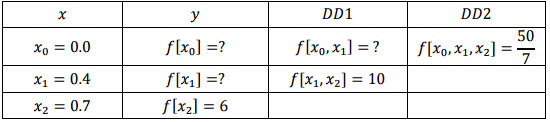

Determine los valores faltantes y complete el polinomio de interpolación.

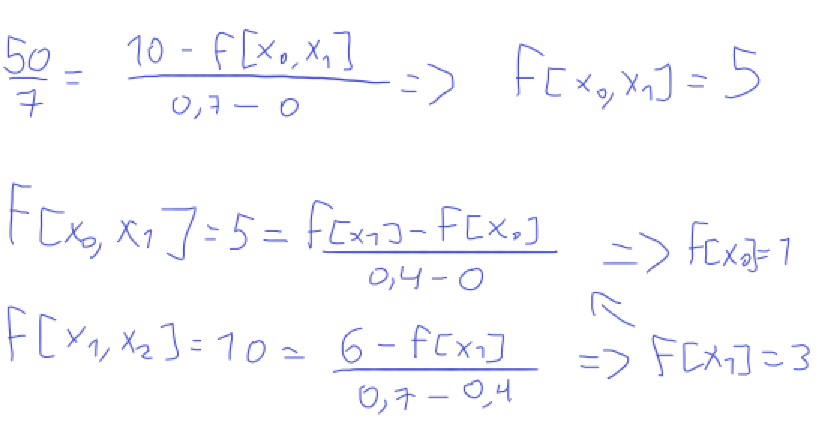


$$P=1+5*\left(x\right)+\left(50/7\right)*\left(x\right)*\left(x-0\ldotp 4\right)$$



$$P=\frac{50x^2 +15x+7}{7}$$


%yasta

$$P = 5\,\mathrm{xint}+\frac{50\,\mathrm{xint}\,\left(\mathrm{xint}-\frac{2}{5}\right)}{7}+1$$

5.Determine todos los valores de a, b, c y d, tales que

Es un trazador cúbico con nodos 0, 1, 2. 

a

a =      0


6. Determine, mediante trazadores cúbicos, la interpolación de los datos en  la siguiente tabla:

a

a =      0


7.Use la fórmula de alta precisión apropiada para determinar la  aproximación que completará la siguiente tabla:

a

a =      0


8.Mediante el algoritmo de integración de Romberg, determine con una  precisión de, por lo menos, cinco (5) cifras decimales el valor de la siguiente  integral:

a

a =      0


9. si $\int_0^{0\ldotp 8} f\left(x\right)\textrm{dx}=2,$y tenemos la siguiente tabla:

Emplee la Regla de Simpson 1/3 para estimar 𝑓(0.7)

%solucionamos con x=0.7 f(0.7)=xint e igualamos a 2
Sol=SimpsonX13(0,0.8,9)

$$Sol = \frac{2\,\mathrm{xint}}{15}+\frac{8}{5}$$

%despejamos Sol=2
f= (2-8/5)*15/2

f =    2.999999999999999


%f(0.7) debe ser 3

10.Emplee la combinación de reglas de integración de Simpson con doce  (12) subintervalos para obtener un valor aproximado de la siguiente integral: 

g10= @(x) (sin(x)/x);
Simpsoneven(0,1,12,g10,0,1,0)

ans =    NaN


11. Emplee la combinación de reglas de integración de Simpson con seis (6) subintervalos para obtener un valor aproximado de la siguiente integral:

g11= @(x) exp(x.^2);
Simpsoneven(0,1,6,g11,0,1,1)

ans =    1.475730582535002


12.Calcule el valor de la integral de los siguientes datos, utilizando  combinación de las reglas de Simpson y del Trapecio.

x=[0 0.1 0.2 0.28 0.32 0.36 0.4 0.55 0.7 0.8 0.86 0.95 1];
y1= [3.3166 3.3007 3.2831 3.2676 3.2594 3.2509 3.2420 3.2054 3.1633 3.1320 3.1118 3.0796 3.0607];
ff=0;
Simpsonuneven(n,g11,x,y1,ff)

Unrecognized function or variable 'n'.